# Tutorial: Script-level information for models

In this tutorial, we will consider the scripts for simulating an empirical one-compartment and a mechanistic 12-compartment model. The structure of the model files has been discussed in another tutorial. The main difference between the two models is their parametrization: while the empirical model uses parameters at the script level, the mechanistic model derives parameters from physiological and drug-related information.

We first define an observable and allocate two virtual individuals.

obs = Observable('SimplePK','pla','total','Mass/Volume');
indv = Individual('Virtual',2);

#### Empirical one-compartment model

Then, we specify the Individual object for the one-compartment model. We provide a dosing and a sampling scheme. The empty physiology of this individual is sufficient, because the model doesn't contain any covariate model, so we don't need to specify anything here. Also, no DrugData object is required. Next, the model function is specified.

indv(1).name = '1-cmt model (Warfarin)';
indv(1).dosing     = Oral('Warfarin', 0*u.h, 15*u.mg);
indv(1).sampling   = Sampling([0 24]*u.h, obs);
indv(1).model      = empirical1CMT_PLASMA_macroConstants_linearCL;

And now we come to the main part, specifying parameters at the script level. This is done via function `parameters()`. We provide a name-value pair for each parameter: volume, clearance, absorption rate and bioavailability. 

indv(1).model.par  = parameters(...
    'V',          10.9*u.L, ...
    'CL',         0.27*u.L/u.h, ...
    'lambda_po',  1.3/u.h, ...
    'F',          1);

Function "parameters" creates a struct, a standard MATLAB object, but it also checks that each element in the struct is a numeric scalar variable. That is, you cannot declare any non-scalar or non-numeric variable as a parameter.

#### Mechanistic 12-compartment model

Now we come to the 12-compartment model. It has the same dosing and sampling scheme as above, but in addition it requires a physiology, which we get here for a reference individual. 

indv(2).name = '12-cmt model (Warfarin)';

indv(2).dosing     = Oral('Warfarin', 0*u.h, 15*u.mg);
indv(2).drugdata   = DrugData('Warfarin','species','human');
indv(2).sampling   = Sampling([0 24]*u.h, obs);
indv(2).physiology = Physiology('human35m');

indv(2).model      = sMD_PBPK_12CMT_wellstirred;

Then, after providing a handle to the model function, a so-called model option is defined, the tissue partitioning method. Model options can be used to pass non-scalar or non-numeric quantities from a script to a model, that is, those quantities that do not qualify as a parameter. Here, the model option is a function handle to the Rodgers&Rowland method, this means it's non-numeric.

indv(2).model.options.tissuePartitioning = @rodgersrowland;

#### Simulating the two models 

Finally, the two models are initialized, simulated and plotted:

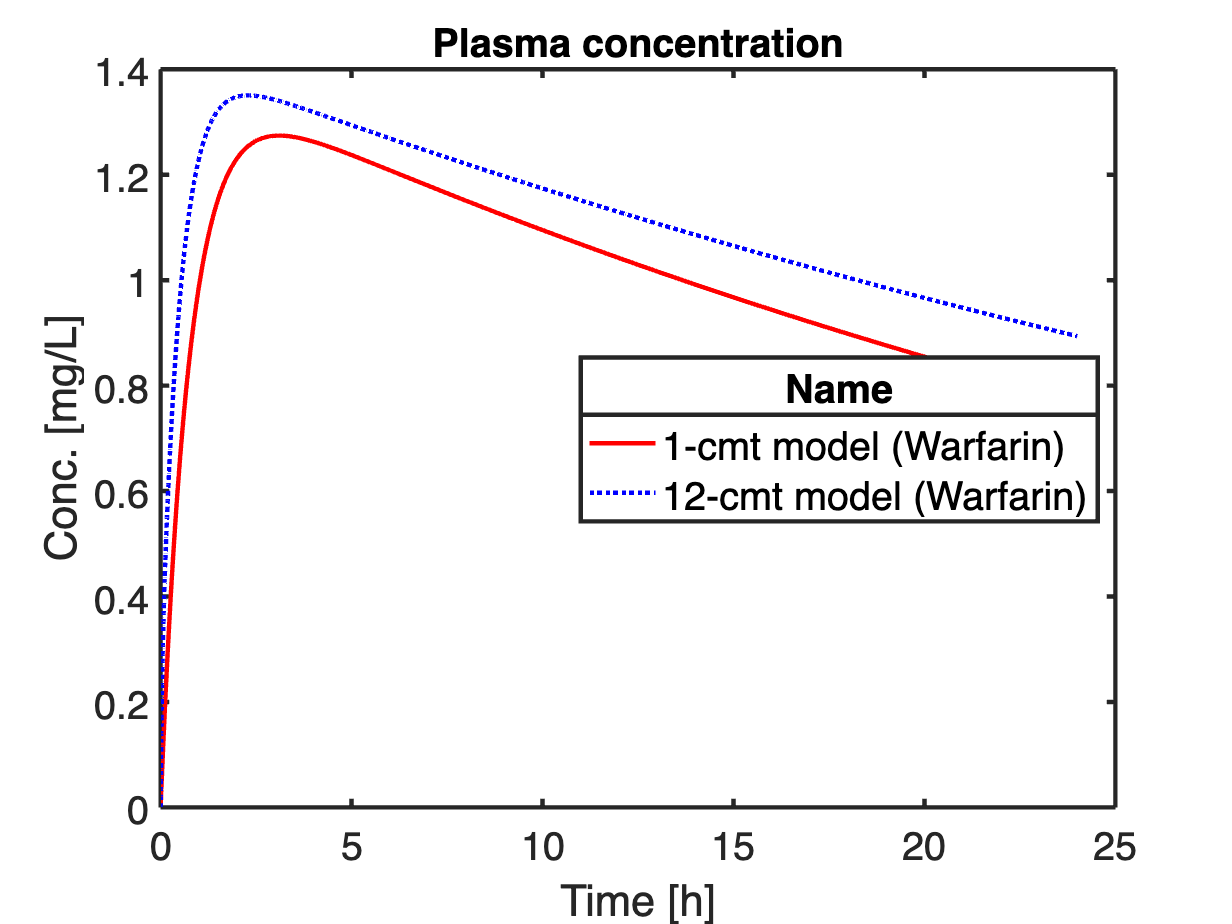

initialize(indv)
simulate(indv)

defaultPlots(indv,'plasmaConcentration','yunit','mg/L')